% Need to first run frequnecy analysis
% in simulink to get the chirp response
% Assume the variable is already in the workspace
nx = 1:10;
est_ss_n4sid = n4sid(chirp_frd, nx)


est_ss_n4sid =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10
   x1    0.07944     32.67  -0.02116     31.86    0.3067    -47.68     11.76     37.84    0.2304     31.57
   x2     -9.743    -1.513     62.27    -5.756    -37.43     15.19     -0.69    -15.66    -21.98    -13.06
   x3   -0.02378    -30.26   -0.3069     101.1    0.7179    -87.62     19.77      65.8    0.8006     51.62
   x4     -3.001    -2.502    -60.79    -9.507    -110.4     25.09    -2.691    -25.51    -36.56    -21.54
   x5   -0.05522     7.341    0.2977     72.33   -0.7425       207     -33.7    -115.9    -1.445    -72.51
   x6       2.44     4.889     24.28     18.57    -147.2    -49.02     12.66     56.05     117.7     41.96
   x7    -0.9649    -1.337    -4.822    -5.134     19.71     8.107    -2.353    -524.3    -54.57    -1

% Plot the bode lot of the state space


est_ss_n4sid =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10
   x1    0.07944     32.67  -0.02116     31.86    0.3067    -47.68     11.76     37.84    0.2304     31.57
   x2     -9.743    -1.513     62.27    -5.756    -37.43     15.19     -0.69    -15.66    -21.98    -13.06
   x3   -0.02378    -30.26   -0.3069     101.1    0.7179    -87.62     19.77      65.8    0.8006     51.62
   x4     -3.001    -2.502    -60.79    -9.507    -110.4     25.09    -2.691    -25.51    -36.56    -21.54
   x5   -0.05522     7.341    0.2977     72.33   -0.7425       207     -33.7    -115.9    -1.445    -72.51
   x6       2.44     4.889     24.28     18.57    -147.2    -49.02     12.66     56.05     117.7     41.96
   x7    -0.9649    -1.337    -4.822    -5.134     19.71     8.107    -2.353    -524.3    -54.57    -1

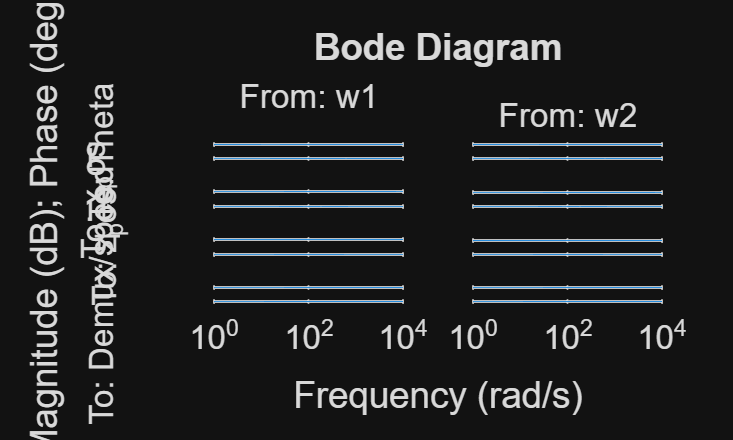

bode(est_ss_n4sid)

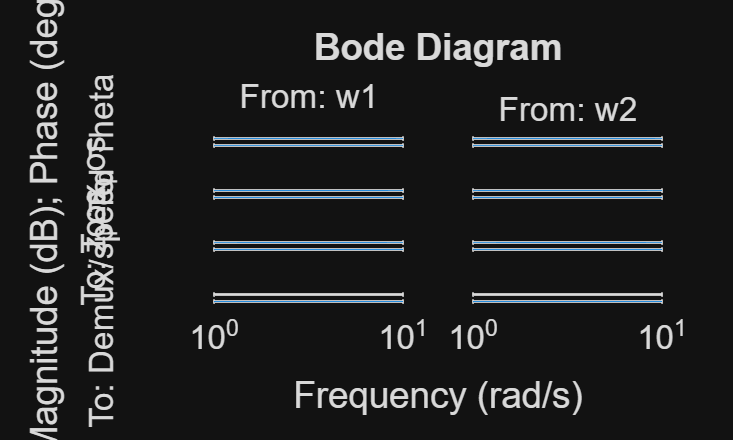

bode(model_statespace)

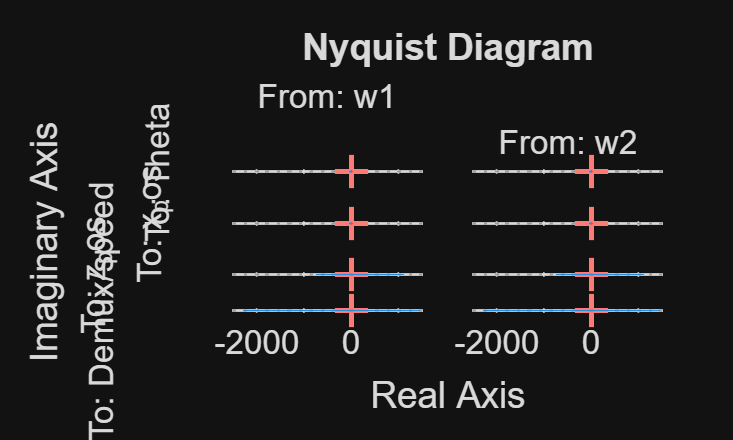

nyquist(est_ss_n4sid)

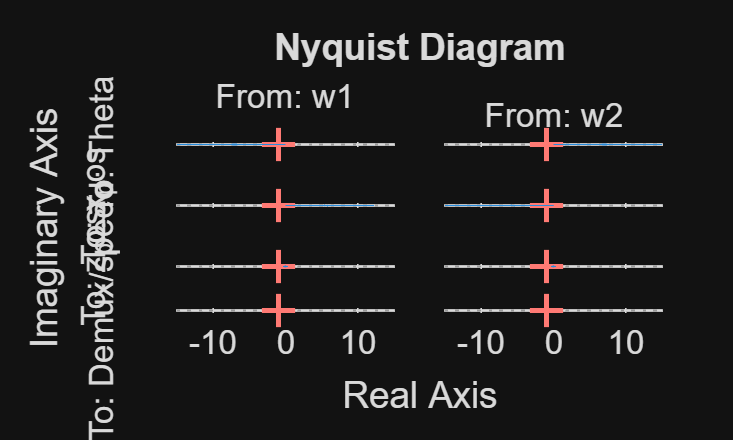

nyquist(model_statespace)

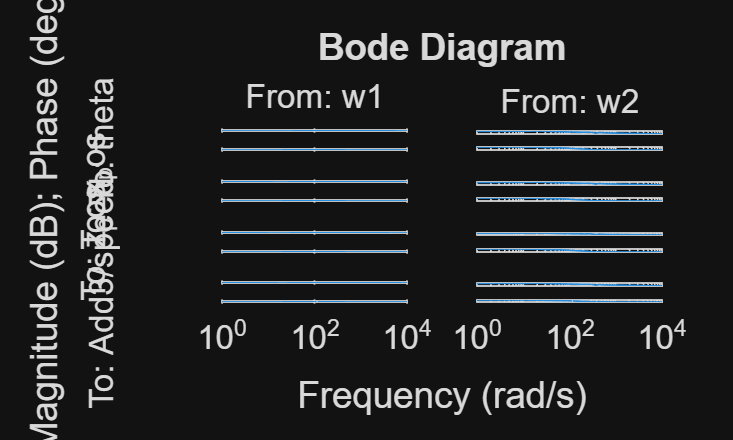

% Create a new frd from the estimated state space


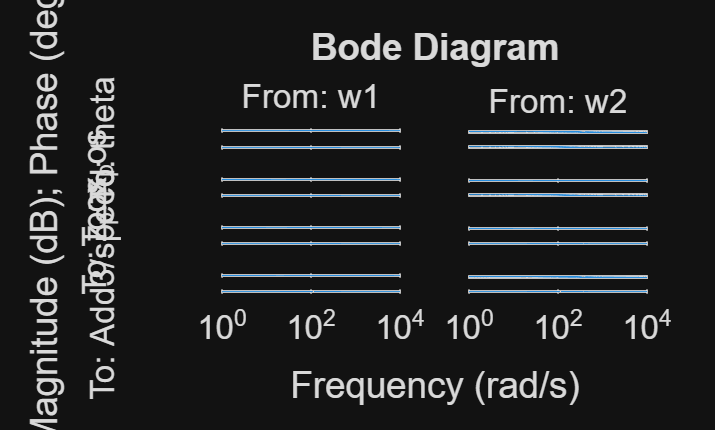

est_noisy_ss = n4sid(noisy_frd);
bode(est_noisy_ss)


io(1) = linio('est_noisy_ss', 1, 'input');  % Input 1 (w1)
io(2) = linio('est_noisy_ss', 2, 'input');  % Input 2 (w2)

% 2. Define the 4 Output points
io(3) = linio('est_noisy_ss', 1, 'output'); % Output 1 (Theta)
io(4) = linio('est_noisy_ss', 2, 'output'); % Output 2 (x_pos)
io(5) = linio('est_noisy_ss', 3, 'output'); % Output 3 (z_pos)
io(6) = linio('est_noisy_ss', 4, 'output'); % Output 4 (speed)


frd_of_est = frestimate(est_noisy_ss, io, in_chirp1);

Error using frestimate (line 121)
The first input argument in "frestimate" must be a valid model name.